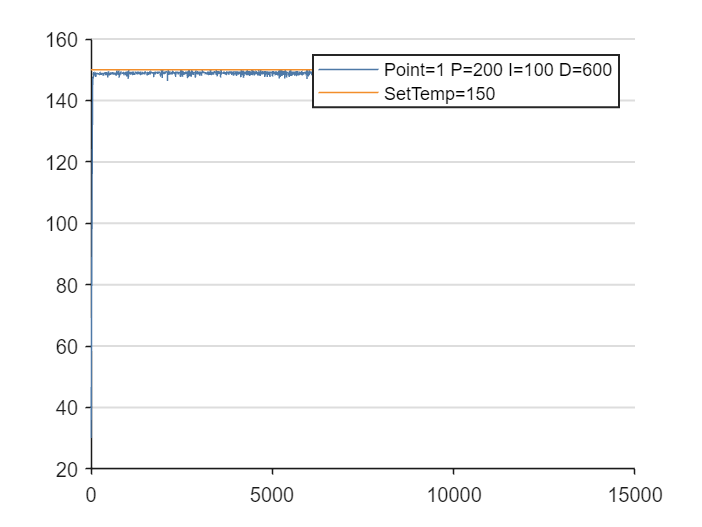

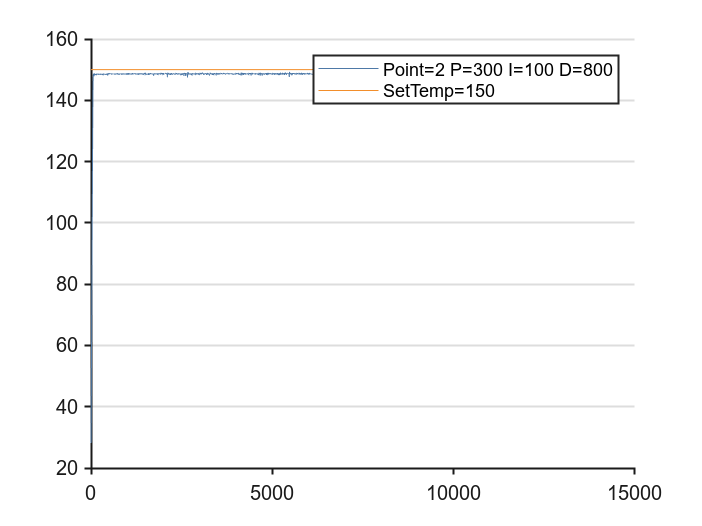

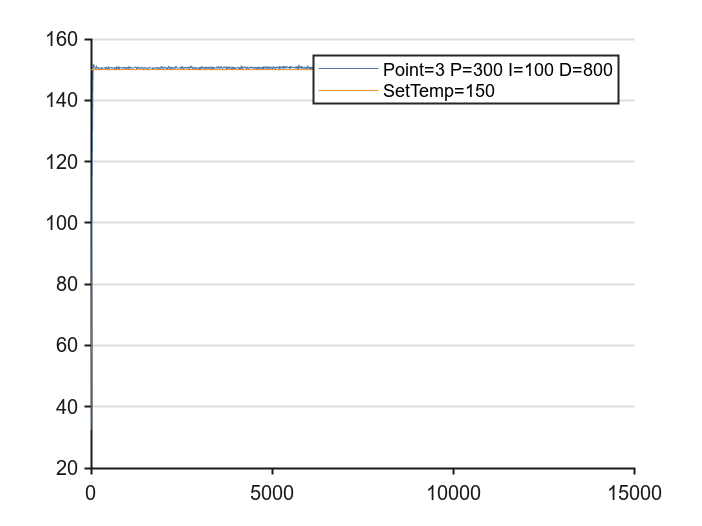

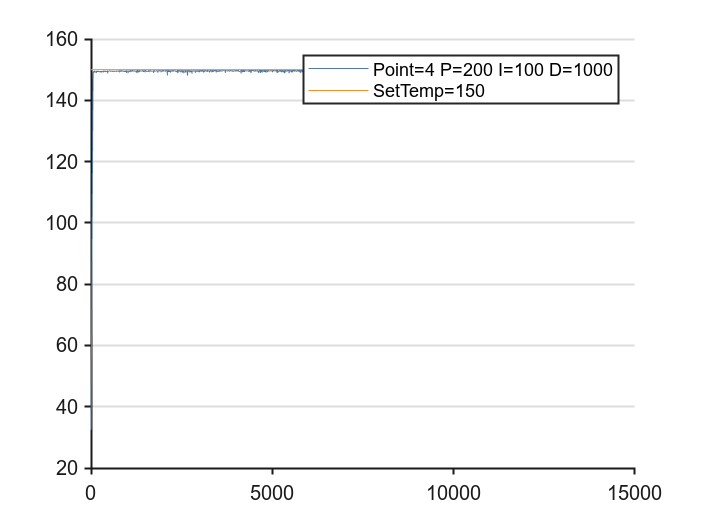

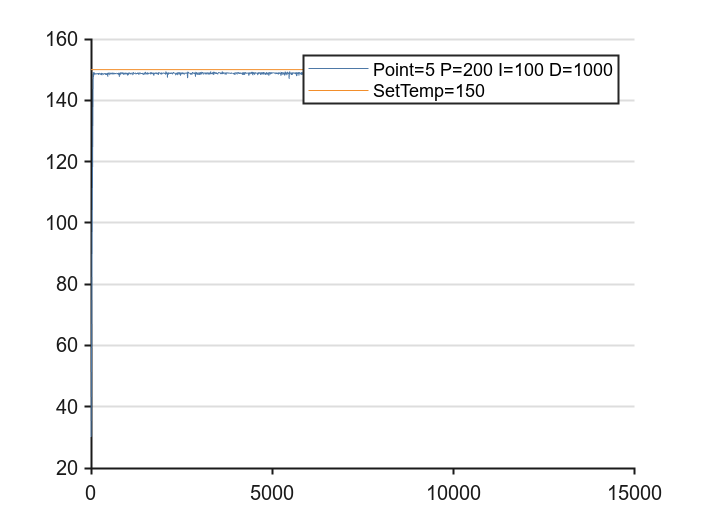

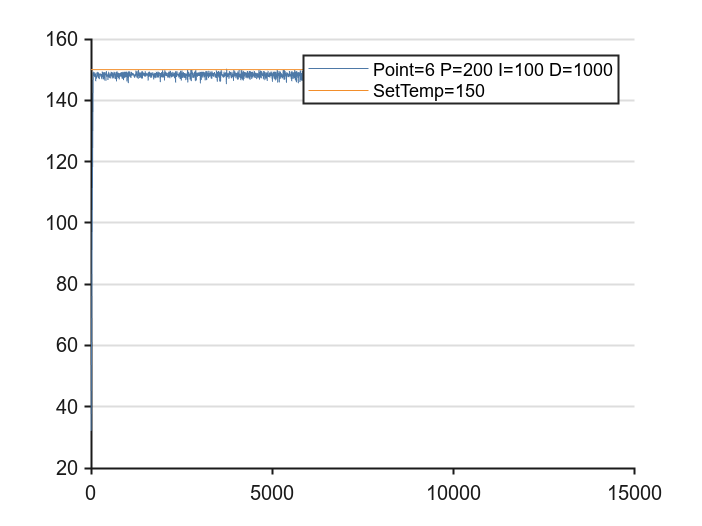

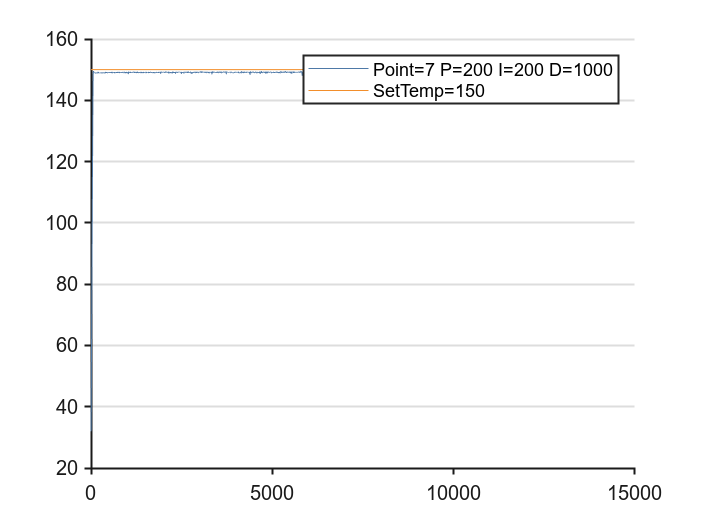

% 单个文件读取后的图表绘制
% 大致逻辑：读取文件名获取基本信息（当前设定温度，七个点的 PID 值）
% 读取文件内数据，分别绘制每个点的曲线图，最后绘制一张七个点的曲线图，各图包含示例，调整曲线图样式。
clear;
mycolor = [ 058 013 096 
            101 068 150 
            151 141 190 
            198 196 223 
            235 236 242 
            252 230 201 
            253 193 117 
            228 137 030 
            181 090 006 
            127 059 008]./255;
mycolor1 = [
    0.3059    0.4745    0.6549
    0.9490    0.5569    0.1686
    0.8824    0.3412    0.3490
    0.4627    0.7176    0.6980
    0.3490    0.6314    0.3098
    0.9294    0.7882    0.2824
    0.6902    0.4784    0.6314
    1.0000    0.6157    0.6549
    0.6118    0.4588    0.3725
    0.7294    0.6902    0.6745
    ];
filepath = "E:/MatlabWorkStation/temperatureprogressionexperiment/temp150_200_100_600_300_100_800_300_100_800_200_100_1000_200_100_1000_200_100_1000_200_200_1000_0.5s.txt";
[filepath,name,ext] = fileparts(filepath);
str = strsplit(name,'_');
parastr(7,3) = string(0);
% 得到七个点的 P、I、D 参数值
for p_i = 1:7
    for p_j = 3:-1:1
        parastr(p_i,(4 - p_j)) = str(p_i*3 - p_j + 2);
    end
end

% 预准备表头名称
TableColumnNames = {'pt1','pt2','pt3','pt4','pt5','pt6','pt7',...
                    'pst1','pst2','pst3','pst4','pst5','pst6','pst7',...
                    'pp1','pp2','pp3','pp4','pp5','pp6','pp7'};

% 读取表格数据，表头名称赋值
DATA = readtable("temperatureprogressionexperiment\temp150_200_100_600_300_100_800_300_100_800_200_100_1000_200_100_1000_200_100_1000_200_200_1000_0.5s.txt");
DATA.Properties.VariableNames = TableColumnNames;
% arraydata(height(DATA),7) = (0);

% 根据数据获取 X 轴长度
X = linspace(1,height(DATA),height(DATA));

% 绘制各个点曲线图
for f_i = 1:1:7
    figure(f_i);
    plot(X,table2array(DATA(:,f_i)), ...
        'DisplayName',sprintf("Point=%d P=%s I=%s D=%s",f_i,parastr(f_i,1),parastr(f_i,2),parastr(f_i,3)));
    hold on;
    plot(X,table2array(DATA(:,f_i + 7)), ...
        'DisplayName',sprintf("SetTemp=%s",extractAfter(str(1),"temp")));
    set(gca,'Box','off', ...                                    % 边框开关
        'LineWidth',1, ...                                  % 线宽（非数据线）
        'XGrid','off','YGrid','on', ...                      % 网格开关
        'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
        'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
        'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
    colororder(mycolor1);
    hold off;
    legend;
end

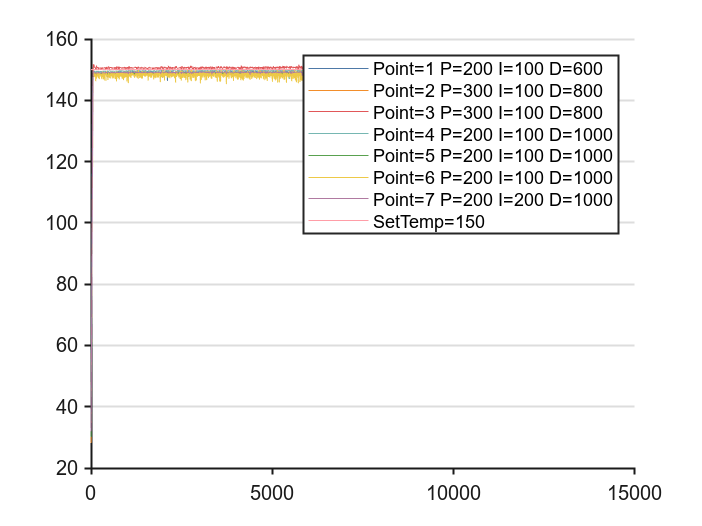


% 绘制七个点的总曲线图
    figure;
for tf_i = 1:1:7
    plot(X,table2array(DATA(:,tf_i)), ...
        'DisplayName',sprintf("Point=%d P=%s I=%s D=%s",tf_i,parastr(tf_i,1),parastr(tf_i,2),parastr(tf_i,3)));
    hold on;
end
plot(X,table2array(DATA(:,8)), ...
    'DisplayName',sprintf("SetTemp=%s",extractAfter(str(1),"temp")));
set( gca,'Box','off', ...                               % 边框开关
    'LineWidth',1, ...                                  % 线宽（非数据线）
    'XGrid','off','YGrid','on', ...                     % 网格开关
    'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
    'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
    'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
colororder(mycolor1);
hold off;
legend;

% 批量读取文件夹内文件数据，并绘制相应的曲线图
Folder = "E:/MatlabWorkStation/temperatureprogressionexperiment/";
Files = dir(Folder);                % 获取文件夹路径下文件，结构体类型
Files = Files(~[Files.isdir]);      % 去掉本身和父文件夹，剩余的即为文件个数
FilesNum = length(Files);            % 获取文件个数
DataCell = cell(1,FilesNum);         % 创建数据存储元胞
XCell = cell(1,FilesNum);
pCell = cell(1,FilesNum);
TableColumnNames = {'pt1','pt2','pt3','pt4','pt5','pt6','pt7',...
                    'pst1','pst2','pst3','pst4','pst5','pst6','pst7',...
                    'pp1','pp2','pp3','pp4','pp5','pp6','pp7'};

% 读取文件中温度有关数据
for i = 1:FilesNum
    filename = fullfile(Folder, Files(i).name);
    str = strsplit(Files(i).name,'_');
    DataCell{i} = readtable(filename);
    DataCell{i}.Properties.VariableNames = TableColumnNames;
    figure(i);
    XCell{i} = linspace(1,height(DataCell{i}),height(DataCell{i}));
    pCell{i} = plot(XCell{i}, ...
                    DataCell{i}.pt1, ...
                    'DisplayName',sprintf("SetTemp=%s P=%s I=%s D=%s",extractAfter(str{1},4),str{2},str{3},str{4}));
    set(gca,'Box','off', ...                                    % 边框开关
        'LineWidth',1, ...                                  % 线宽（非数据线）
        'XGrid','on','YGrid','on', ...                      % 网格开关
        'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
        'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
        'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
    legend;
end


% 批量读取文件夹内文件数据，并绘制相应的曲线图
% Folder = "E:/MatlabWorkStation/temperatureprogressionexperiment/";
Folder = "D:/EDProgram/MatlabForHeater/temperatureprogressionexperiment/";
Files = dir(Folder);                % 获取文件夹路径下文件，结构体类型
Files = Files(~[Files.isdir]);      % 去掉本身和父文件夹，剩余的即为文件个数
FilesNum = length(Files);           % 获取文件个数
DataCell = cell(1,FilesNum);        % 创建文件数据元胞
XCell = cell(1,FilesNum);           % 创建 X 轴长度元胞
parad = dictionary;                 % 创建 PID 参数字典
paracell = cell(1,7);               % 创建 PID 参数元胞
parastr(7,3) = string(0);           % 预设 PID 参数字符串数组
pCell = cell(1,FilesNum);           
TableColumnNames = {'pt1','pt2','pt3','pt4','pt5','pt6','pt7',...
                    'pst1','pst2','pst3','pst4','pst5','pst6','pst7',...
                    'pp1','pp2','pp3','pp4','pp5','pp6','pp7'};

for i = 1:FilesNum
    str = string(strsplit(Files(i).name,'_'));
    for p_i = 1:7
        for p_j = 3:-1:1
            parastr(p_i,(4 - p_j)) = str(p_i*3 - p_j + 2);
        end
    end
    parad(str{1}) = parastr;
end

错误使用  () 
键和值的维度必须兼容，或值必须为标量。

     

% 读取文件中温度有关数据
for i = 1:FilesNum
    filename = fullfile(Folder, Files(i).name);
    str = strsplit(Files(i).name,'_');
    DataCell{i} = readtable(filename);
    DataCell{i}.Properties.VariableNames = TableColumnNames;
    figure(i);
    XCell{i} = linspace(1,height(DataCell{i}),height(DataCell{i}));
    plot(XCell{i}, ...
         DataCell{i}.pt1, ...
         'DisplayName',sprintf("SetTemp=%s P=%s I=%s D=%s",extractAfter(str{1},4),str{2},str{3},str{4}));
    set(gca,'Box','off', ...                                % 边框开关
        'LineWidth',1, ...                                  % 线宽（非数据线）
        'XGrid','on','YGrid','on', ...                      % 网格开关
        'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
        'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
        'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
    legend;
end


